%% ========================================================================
%  EANN_MO_Pareto_Q1_noGPU.m
%  ------------------------------------------------------------------------
%  ¿QUÉ HACE ESTE CÓDIGO?
%   • Red EANN (MLP 2 capas + cabeza residual) que mapea features de ab -> [k1..k5,c1..c5]
%   • Optimiza TODOS los pesos/sesgos de la red con evolución MULTI-OBJETIVO (gamultiobj)
%   • 2 FASES: Exploración (diversidad) -> Explotación (nube estrecha)
%   • 3 OBJETIVOS simultáneos:
%       f1: error temporal ponderado (x y v) por piso
%       f2: alineación de picos espectrales (modal) exp vs sim (FFT puro MATLAB)
%       f3: regularización física (A*g<=b + suavidad + log-escala)
%   • Genera el FRENTE DE PARETO (3D + proyecciones 2D)
%   • Selecciona el "KNEE POINT" y lo refina por fmincon
%   • Grafica por piso (x y v) y entrega la RED OPTIMIZADA (pesos/sesgos)
%  ------------------------------------------------------------------------
%  ENTRADAS:
%    datosFiltradosSismoYOct8.mat  (variables: ab [Nx1], xr [Nx5], vr [Nx5], t [Nx1])
%    metrics.m                     (usado para MSE/RMSE por piso)
%  SALIDAS:
%    - Figuras del frente de Pareto y por piso
%    - Archivo: EANN_MO_Q1_result.mat con:
%        theta_star (pesos/sesgos optimizados), dims de la red, g_star,
%        mu_x/sig_x (normalización features), lb/ub efectivos, Pareto, etc.
%  ------------------------------------------------------------------------
%  NOTAS:
%    • Integrador Tustin (sin lsim/MEX): compatible con parpool 'Processes'
%    • Código sin GPU (solo CPU + paralelo por procesos)
% ========================================================================

close all; clc; rng(1);                  % limpiar figuras, consola y fijar semilla

%% === Paralelo (solo procesos) ==========================================
% Cierra cualquier pool previo y fuerza pool de PROCESOS (no threads)
try
    p = gcp('nocreate');                 % consulta pool activo
    if isempty(p) || ~strcmpi(p.Type,'processes')
        if ~isempty(p), delete(p); end   % si había pool de otro tipo, ciérralo
        parpool('Processes');            % abre pool de procesos
    end
catch
    warning('Sin parpool; ejecuto en secuencial.');
end

%% ========================= CARGA DE DATOS ===============================
load('datosFiltradosSismoYOct8.mat','ab','xr','vr','t'); % señales experimentales
ab = ab(:);                                              % forzar columna
assert(size(xr,2)==5 && size(vr,2)==5 && numel(t)==numel(ab), ...
       'Datos no válidos: dimensiones inconsistentes.');

%% ========================= MODELO FÍSICO ================================
M = diag([11.773 9.17 9.14 9.12 9.08]);                 % masas (5 DOF)
lbG = [7000 7000 7000 7000 7000   0   0   0   0   0]';   % límites inferiores
ubG = [12000 12000 12000 12000 12000 100 100 100 100 100]'; % límites superiores
g_seed = [8000 8000 8000 8000 8000  20 20 20 20 20]';    % semilla física (K≈8000, C≈20)

% Restricciones lineales A*g <= b (monotonía/razones físicas entre k_i)
Aineq = [ 0.6 -1   0   0   0   0 0 0 0 0;
         -1.4  1   0   0   0   0 0 0 0 0;
           0  0.6 -1   0   0   0 0 0 0 0;
           0 -1.4  1   0   0   0 0 0 0 0;
           0   0  0.6 -1   0   0 0 0 0 0;
           0   0 -1.4  1   0   0 0 0 0 0;
           0   0   0  0.6 -1   0 0 0 0 0;
           0   0   0 -1.4  1   0 0 0 0 0;
           0   0   0   0   0  0.6 -1   0   0   0;
           0   0   0   0   0 -1.4  1   0   0   0;
           0   0   0   0   0   0  0.6 -1   0   0;
           0   0   0   0   0   0 -1.4  1   0   0;
           0   0   0   0   0   0   0  0.6 -1   0;
           0   0   0   0   0   0   0 -1.4  1   0;
           0   0   0   0   0   0   0   0  0.6 -1;
           0   0   0   0   0   0   0   0 -1.4  1];
bineq = zeros(16,1);                                    % lado derecho

%% ========================= FEATURES DE ENTRADA ==========================
NLAGS = 128;                                            % tamaño de ventana de lags de ab
[Xfeat, mu_x, sig_x] = make_features(ab, NLAGS);        % extracción de features
D  = numel(Xfeat);                                      % dimensión de entrada a la red
Xn = (Xfeat - mu_x) ./ (sig_x + 1e-12);                 % normalización robusta

%% ========================= ARQUITECTURA EANN ===========================
H1 = 32; H2 = 16;                                       % neuronas por capa oculta
ny_main = 10; ny_res = 10;                              % 10 salidas físicas + residuales
% Conteo de parámetros por bloque (para empaquetar/desempaquetar)
nW1=H1*D;  nb1=H1;  nW2=H2*H1; nb2=H2;
nW3=ny_main*H2; nb3=ny_main;
nW3b=ny_res*H2; nb3b=ny_res;
nvars = nW1+nb1+nW2+nb2+nW3+nb3+nW3b+nb3b;             % tamaño del cromosoma

% Funciones de empaquetado/desempaquetado
pack=@(W1,b1,W2,b2,W3,b3,W3b,b3b) [W1(:); b1(:); W2(:); b2(:); W3(:); b3(:); W3b(:); b3b(:)];
unpack=@(th) deal( ...
    reshape(th(1:nW1),[H1,D]), ...
    reshape(th(nW1+(1:nb1)),[H1,1]), ...
    reshape(th(nW1+nb1+(1:nW2)),[H2,H1]), ...
    reshape(th(nW1+nb1+nW2+(1:nb2)),[H2,1]), ...
    reshape(th(nW1+nb1+nW2+nb2+(1:nW3)),[ny_main,H2]), ...
    reshape(th(nW1+nb1+nW2+nb2+nW3+(1:nb3)),[ny_main,1]), ...
    reshape(th(nW1+nb1+nW2+nb2+nW3+nb3+(1:nW3b)),[ny_res,H2]), ...
    reshape(th(nW1+nb1+nW2+nb2+nW3+nb3+nW3b+(1:nb3b)),[ny_res,1]) );

% Inicialización "semilla" (W,b = 0 salvo b3 que imprime g_seed en [lb,ub])
W1z=zeros(H1,D); b1z=zeros(H1,1);
W2z=zeros(H2,H1); b2z=zeros(H2,1);
W3z=zeros(ny_main,H2);
W3bz=zeros(ny_res,H2); b3bz=zeros(ny_res,1);
LBtheta = -1*ones(1,nvars);  UBtheta = 1*ones(1,nvars);  % límites del cromosoma

%% ========================= PESOS/OBJETIVOS =============================
% Pesos de penalizaciones en el objetivo f3 (físico)
lambda_lin   = 1e6;                                   % peso violación A*g<=b
lambda_smooth= 1e2;                                   % suavidad (TV cuadrática)
lambda_log   = 5e-1;                                  % log-escala entorno g_seed

% Configuración espectral (FFT puro MATLAB, sin MEX)
KFFT   = 2048;                                       % tamaño FFT
band   = 2:round(KFFT/3);                            % banda útil (evita DC/alias)
w_time = time_weights_from_ab(ab);                   % pesos temporales

%% ========================= FASE 1: EXPLORACIÓN =========================
% Límites "efectivos" alrededor de la semilla (ancho)
pct1 = 0.40;
lb1  = max(lbG, g_seed.*(1-pct1));
ub1  = min(ubG, g_seed.*(1+pct1));

% Construir theta_seed que imprime g_seed en [lb1,ub1]
theta_seed = make_theta_seed(g_seed, lb1, ub1, pack, W1z, b1z, W2z, b2z, W3z, W3bz, b3bz);

% Población inicial: 30% nube jittered alrededor de la semilla + resto aleatorio
popSize1   = 220;
nSeeds1    = max(1, round(0.30*popSize1));
sigmaTh1   = 0.15;
seedCloud1 = repmat(theta_seed(:).', nSeeds1, 1) + sigmaTh1*randn(nSeeds1, nvars);
randRest1  = LBtheta + (UBtheta-LBtheta).*rand(popSize1-nSeeds1, nvars);
initPop1   = [seedCloud1; randRest1];

% Opciones de gamultiobj (exploración)
opts1 = optimoptions('gamultiobj', ...
   'PopulationSize', popSize1, ...
   'InitialPopulationMatrix', initPop1, ...
   'SelectionFcn', {@selectiontournament,4}, ...
   'CrossoverFcn', @crossoverscattered, ...
   'CrossoverFraction', 0.85, ...
   'MutationFcn', {@mutationgaussian, 0.55, 0.95}, ...
   'ParetoFraction', 0.35, ...
   'FunctionTolerance', 1e-10, ...
   'MaxGenerations', 160, ...
   'MaxStallGenerations', 120, ...
   'UseParallel', true, 'Display','iter');

% Fitness multi-objetivo (devuelve [f1 f2 f3])
fitnessMO = @(th) fitness_multi(th, ab, xr, vr, t, Xn, ...
    lb1, ub1, Aineq, bineq, M, unpack, g_seed, ...
    w_time, KFFT, band, lambda_lin, lambda_smooth, lambda_log);

% Ejecutar Fase 1
[ThetaPareto1, Fpareto1] = gamultiobj(fitnessMO, nvars, [],[],[],[], LBtheta, UBtheta, [], opts1);


Multi-objective optimization:
5124 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationgaussian

                              Average            Average
Generation   Func-count    Pareto distance    Pareto spread
    1           220                 1                 1
    2           440           0.29196                 1
    3           660         0.0408651                 1
    4           880           0.27051                 1
    5          1100          0.289651           0.30564
    6          1320          0.225975                 1
    7          1540          0.290307          0.246494
    8          1760          0.299422          0.244091
    9          1980          0.209793          0.195131
   10          2200          0.258393                 1
   11          2420          0.193204          0.352952
   12          2640          0.227372           0.37769



%% ========================= FASE 2: EXPLOTACIÓN =========================
% Límites más estrechos alrededor de la semilla (para estabilidad)
pct2 = 0.18;
lb2  = max(lbG, g_seed.*(1-pct2));
ub2  = min(ubG, g_seed.*(1+pct2));

% Re-construir semilla con lb2/ub2
theta_seed2 = make_theta_seed(g_seed, lb2, ub2, pack, W1z, b1z, W2z, b2z, W3z, W3bz, b3bz);

% Población: nubes alrededor del frente 1 + semilla estricta
popSize2 = 160;
sigmaTh2 = 0.06;
idxSample = randi(size(ThetaPareto1,1), popSize2-1, 1);           % muestrea sol. no dominadas
initPop2  = ThetaPareto1(idxSample, :) + sigmaTh2*randn(popSize2-1, nvars);
initPop2  = [theta_seed2(:).'; initPop2];                          % inyecta semilla
initPop2  = min(max(initPop2, LBtheta), UBtheta);                  % recorte a límites

% Opciones de explotación (más presión, mutación pequeña)
opts2 = optimoptions('gamultiobj', ...
   'PopulationSize', popSize2, ...
   'InitialPopulationMatrix', initPop2, ...
   'SelectionFcn', {@selectiontournament,8}, ...
   'CrossoverFcn', @crossoverintermediate, ...
   'CrossoverFraction', 0.55, ...
   'MutationFcn', {@mutationgaussian, 0.20, 0.995}, ...
   'ParetoFraction', 0.35, ...
   'FunctionTolerance', 1e-12, ...
   'MaxGenerations', 120, ...
   'MaxStallGenerations', 100, ...
   'UseParallel', true, 'Display','iter');

% Fitness Fase 2 (igual, pero con lb2/ub2 para mapear g)
fitnessMO2 = @(th) fitness_multi(th, ab, xr, vr, t, Xn, ...
    lb2, ub2, Aineq, bineq, M, unpack, g_seed, ...
    w_time, KFFT, band, lambda_lin, lambda_smooth, lambda_log);

% Ejecutar Fase 2
[ThetaPareto2, Fpareto2] = gamultiobj(fitnessMO2, nvars, [],[],[],[], LBtheta, UBtheta, [], opts2);


Multi-objective optimization:
5124 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverintermediate
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationgaussian

                              Average            Average
Generation   Func-count    Pareto distance    Pareto spread
    1           160                 1                 1
    2           320          0.191356                 1
    3           480          0.288025                 1
    4           640          0.263365          0.357357
    5           800          0.215645          0.347006
    6           960          0.195831          0.346313
    7          1120          0.264821                 1
    8          1280         0.0254555         0.0146929
    9          1440                 0                 0
   10          1600                 0                 1
   11          1760                 0                 0
   12          1920          0.293723          0.2098


%% ========================= SELECCIÓN DEL "KNEE POINT" ==================
% Unir frentes y seleccionar "rodilla" (punto cercano a utopía [0,0,0])
ThetaPareto = [ThetaPareto1; ThetaPareto2];
Fpareto     = [Fpareto1;     Fpareto2];
[idxKnee, Fknee_n, scales] = select_knee(Fpareto);
theta_knee  = ThetaPareto(idxKnee, :);

% Mostrar resumen en consola
disp('--- Selección de Knee Point ---');

--- Selección de Knee Point ---


disp(table(Fpareto(idxKnee,1),Fpareto(idxKnee,2),Fpareto(idxKnee,3), ...
     'VariableNames',{'f1_time','f2_modal','f3_phys'}));

    f1_time    f2_modal     f3_phys  
    _______    ________    __________

    4.0648     0.11921     1.1959e+07




%% ========================= REFINAMIENTO LOCAL (fmincon) =================
% Scalariza alrededor del knee con pesos inversos a la escala
w = 1./(scales + eps); w = w./sum(w);
f_scalar = @(th) dot(w, fitnessMO2(th));               % combinación convexa

% Opciones fmincon
fminconopts = optimoptions('fmincon','Algorithm','interior-point', ...
    'Display','iter','MaxIterations',200,'SpecifyObjectiveGradient',false);

% Ejecutar refinamiento
[theta_star, fval_star] = fmincon(f_scalar, theta_knee(:), [],[],[],[], LBtheta(:), UBtheta(:), [], fminconopts); %#ok<ASGLU>

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0    5125    1.076696e+00    0.000e+00    7.929e-01

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



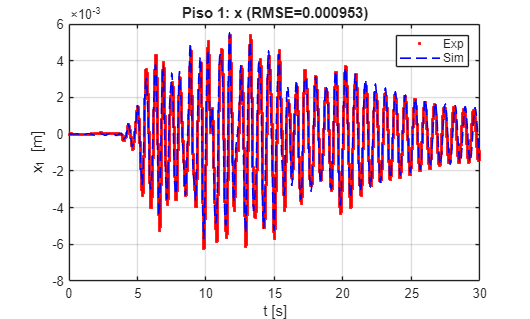

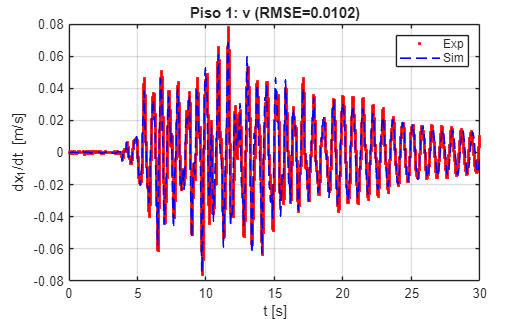

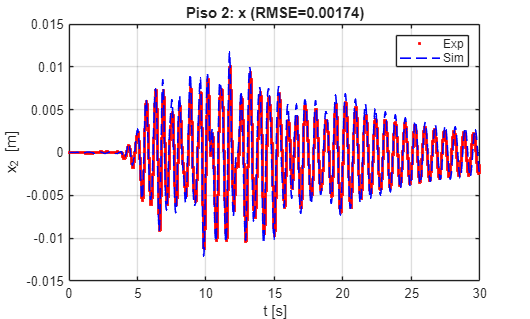

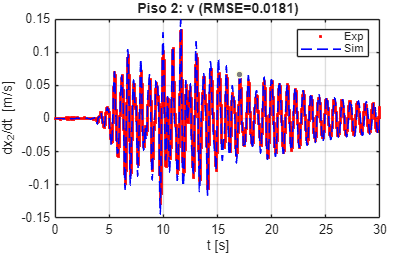

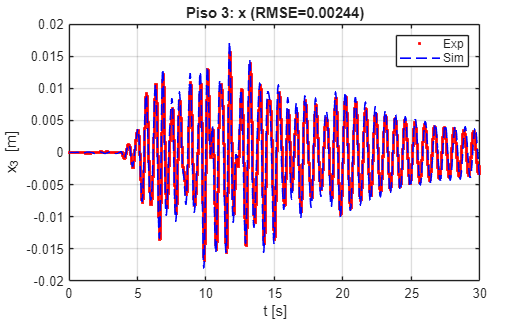

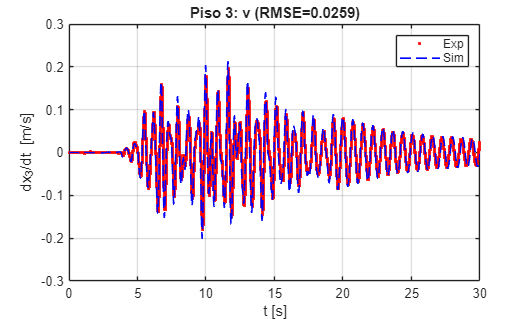

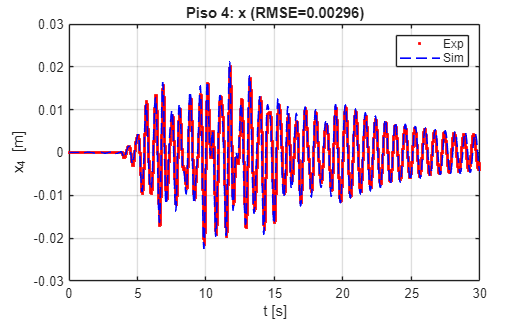

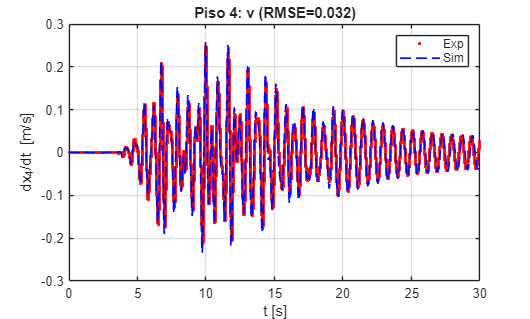


%% ========================= SIMULACIÓN FINAL Y GRÁFICAS =================
% Obtener parámetros físicos a partir de la red optimizada
[g_main, d_g] = mlp_heads(theta_star, Xn, lb2, ub2, unpack);  % mapeo [-1,1]->[lb2,ub2]
g_star = min(max(g_main + d_g, lb2), ub2);                    % saturar a [lb2,ub2]

% Simular edificio con integración Tustin (sin lsim/MEX)
Ye = simulate_building_no_mex(g_star, ab, t, M);              % [x1..x5 v1..v5]

% Calcular métricas por piso (MSE/RMSE) para x y v
n=5; MSE_x=zeros(1,n); RMSE_x=MSE_x; MSE_v=MSE_x; RMSE_v=MSE_x;
for i=1:n
    [MSE_x(i), RMSE_x(i)] = metrics(Ye(:,i),     xr(:,i));
    [MSE_v(i), RMSE_v(i)] = metrics(Ye(:,5+i),   vr(:,i));
end

% ---------- Gráficas por piso ----------
for piso=1:5
    figure('Name',sprintf('Piso %d - Desplazamiento',piso));
    plot(t,xr(:,piso),'.r', t,Ye(:,piso),'--b','LineWidth',1.2); grid on;
    xlabel('t [s]'); ylabel(sprintf('x_%d [m]',piso));
    legend('Exp','Sim'); title(sprintf('Piso %d: x (RMSE=%.3g)',piso,RMSE_x(piso)));

    figure('Name',sprintf('Piso %d - Velocidad',piso));
    plot(t,vr(:,piso),'.r', t,Ye(:,5+piso),'--b','LineWidth',1.2); grid on;
    xlabel('t [s]'); ylabel(sprintf('dx_%d/dt [m/s]',piso));
    legend('Exp','Sim'); title(sprintf('Piso %d: v (RMSE=%.3g)',piso,RMSE_v(piso)));
end

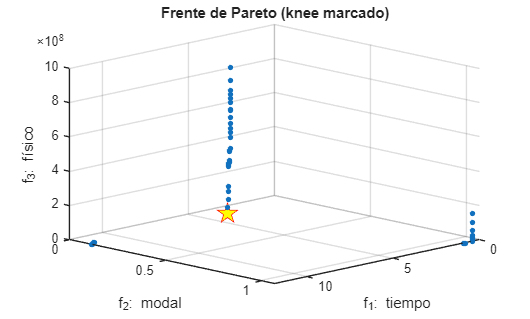


% ---------- Frente de Pareto (3D + proyecciones) ----------
figure('Name','Frente de Pareto 3D');
plot3(Fpareto(:,1), Fpareto(:,2), Fpareto(:,3), '.','MarkerSize',12); grid on; hold on;
plot3(Fpareto(idxKnee,1),Fpareto(idxKnee,2),Fpareto(idxKnee,3),'rp','MarkerSize',16,'MarkerFaceColor','y');
xlabel('f_1: tiempo'); ylabel('f_2: modal'); zlabel('f_3: físico');
title('Frente de Pareto (knee marcado)'); view(135,20);

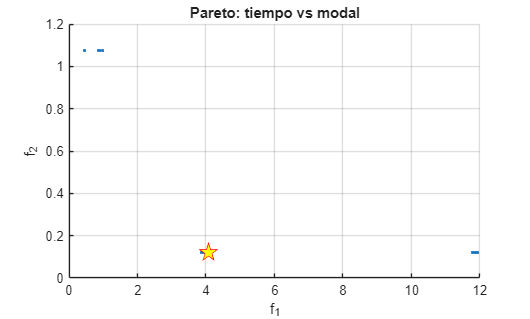


figure('Name','Pareto f1 vs f2');  grid on; hold on;
plot(Fpareto(:,1), Fpareto(:,2), '.'); plot(Fpareto(idxKnee,1),Fpareto(idxKnee,2),'rp','MarkerSize',14,'MarkerFaceColor','y');
xlabel('f_1'); ylabel('f_2'); title('Pareto: tiempo vs modal');

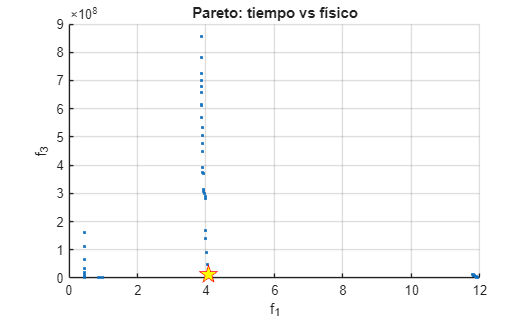


figure('Name','Pareto f1 vs f3');  grid on; hold on;
plot(Fpareto(:,1), Fpareto(:,3), '.'); plot(Fpareto(idxKnee,1),Fpareto(idxKnee,3),'rp','MarkerSize',14,'MarkerFaceColor','y');
xlabel('f_1'); ylabel('f_3'); title('Pareto: tiempo vs físico');

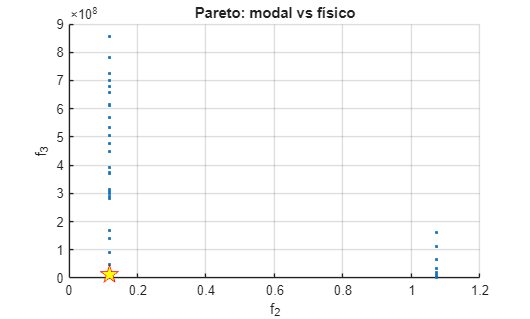


figure('Name','Pareto f2 vs f3');  grid on; hold on;
plot(Fpareto(:,2), Fpareto(:,3), '.'); plot(Fpareto(idxKnee,2),Fpareto(idxKnee,3),'rp','MarkerSize',14,'MarkerFaceColor','y');
xlabel('f_2'); ylabel('f_3'); title('Pareto: modal vs físico');


% Mostrar parámetros finales
disp('--- g* (k1..k5, c1..c5) ---');

--- g* (k1..k5, c1..c5) ---


disp(array2table(g_star(:)', 'VariableNames', {'k1','k2','k3','k4','k5','c1','c2','c3','c4','c5'}));

      k1        k2        k3        k4        k5       c1      c2      c3      c4       c5  
    ______    ______    ______    ______    ______    ____    ____    ____    ____    ______

    8408.5    8302.1    8554.1    9171.1    9099.7    23.6    23.6    23.6    23.6    20.179




%% ========================= GUARDADO DE LA RED ==========================
net.theta   = theta_star(:);                             % vector de pesos/sesgos optimizados
net.dims    = struct('D',D,'H1',H1,'H2',H2,'ny_main',ny_main,'ny_res',ny_res);
net.scaling = struct('mu_x',mu_x,'sig_x',sig_x,'lb',lb2,'ub',ub2);
net.misc    = struct('g_seed',g_seed,'Aineq',Aineq,'bineq',bineq);
result.MSE_x = MSE_x; result.RMSE_x = RMSE_x; result.MSE_v = MSE_v; result.RMSE_v = RMSE_v;

save('EANN_MO_Q1_result.mat', ...
    'net','g_star','ThetaPareto','Fpareto','idxKnee','theta_star','Fknee_n','w', ...
    'M','t','-v7.3');

disp('Archivo guardado: EANN_MO_Q1_result.mat');

Archivo guardado: EANN_MO_Q1_result.mat



%% ========================= SUBFUNCIONES ================================

function [Xfeat, mu_x, sig_x] = make_features(ab, NLAGS)
% Extrae una ventana de NLAGS muestras con mayor energía y añade 4 stats.
    N = numel(ab); w = max(1,NLAGS);
    if N<=w
        seg = ab;
    else
        sm = conv(ab.^2, ones(w,1)/w, 'same');    % energía móvil
        [~,i0] = max(sm);                          % centro de máxima energía
        i1 = max(1, i0 - floor(w/2));              % inicio ventana
        i2 = min(N, i1 + w - 1);                   % fin
        seg = ab(i1:i2);
        if numel(seg) < w, seg = [seg; zeros(w-numel(seg),1)]; end
    end
    Xlags = seg(end-w+1:end);                      % lags más recientes
    feat  = [sqrt(mean(Xlags.^2)); sum(Xlags.^2); kurtosis(Xlags); skewness(Xlags)];
    Xfeat = [Xlags(:); feat];                      % vector de entrada
    mu_x = mean(Xfeat); sig_x = std(Xfeat);        % normalización
end

function wt = time_weights_from_ab(ab)
% Asigna mayor peso a instantes con mayor |ab| (mejor seguimiento en energía)
    p = ab.^2; p = p - min(p); p = p / max(p + eps);
    wt = 0.3 + 0.7*p;                              % entre 0.3 y 1.0
end

function theta_seed = make_theta_seed(g_seed, lb, ub, pack, W1z, b1z, W2z, b2z, W3z, W3bz, b3bz)
% Construye un cromosoma theta tal que la cabeza principal imprime g_seed.
    g01 = (g_seed - lb) ./ (ub - lb);              % map a (0,1)
    g01 = min(max(g01, 1e-6), 1 - 1e-6);           % evitar atanh(±1)
    z3  = 2*g01 - 1;                                % a (-1,1)
    b3z = atanh(z3);                                % sesgo que imprime g_seed
    theta_seed = pack(W1z, b1z, W2z, b2z, W3z, b3z, W3bz, b3bz);
    theta_seed = theta_seed(:).';                   % fila 1×nvars
end

function [g_main, d_g] = mlp_heads(theta, xfeat, lb, ub, unpack)
% Pasa xfeat (D×1) por la red y mapea a [lb,ub]; residual ±15% (gris).
    [W1,b1,W2,b2,W3,b3,W3b,b3b] = unpack(theta);
    z1 = tanh(W1*xfeat + b1);
    z2 = tanh(W2*z1 + b2);
    z_main = tanh(W3*z2 + b3);                      % [-1,1]
    z_res  = tanh(W3b*z2 + b3b);                    % [-1,1]
    g01 = (z_main + 1)/2;                           % [0,1]
    g_main = lb + (ub - lb).*g01;                   % [lb,ub]
    d_g = 0.15 .* g_main .* z_res;                  % ±15% de corrección
end

function Ye = simulate_building_no_mex(g, ab, t, M)
% Integración Tustin (discreta) del sistema [x;v] con entrada -ab*l.
    k1=g(1);k2=g(2);k3=g(3);k4=g(4);k5=g(5);
    c1=g(6);c2=g(7);c3=g(8);c4=g(9);c5=g(10);
    n=5; Mi = inv(M); l = ones(n,1);
    Cs=[c1+c2,-c2,0,0,0; -c2,c2+c3,-c3,0,0; 0,-c3,c3+c4,-c4,0; 0,0,-c4,c4+c5,-c5; 0,0,0,-c5,c5];
    Ks=[k1+k2,-k2,0,0,0; -k2,k2+k3,-k3,0,0; 0,-k3,k3+k4,-k4,0; 0,0,-k4,k4+k5,-k5; 0,0,0,-k5,k5];
    A=[zeros(n) eye(n); -Mi*Ks -Mi*Cs]; B=[zeros(n,1); -l];
    dt=t(2)-t(1); I=eye(2*n);
    Ad=(I-0.5*dt*A)\(I+0.5*dt*A); Bd=(I-0.5*dt*A)\(dt*B);
    N=numel(t); x=zeros(2*n,1); Ye=zeros(N,2*n);
    for k=1:N
        Ye(k,:) = x.';            % guardar estado actual
        x = Ad*x + Bd*ab(k);      % actualización Tustin
    end
end

function F = fitness_multi(theta, ab, xr, vr, t, Xn, ...
    lb, ub, A, b, M, unpack, g_seed, ...
    w_time, KFFT, band, lambda_lin, lambda_smooth, lambda_log)
% Devuelve el vector de objetivos [f1, f2, f3].
    % ----- MLP -> parámetros físicos -----
    [g_main, d_g] = mlp_heads(theta, Xn, lb, ub, unpack);
    g = min(max(g_main + d_g, lb), ub);            % saturación [lb,ub]

    % ----- Simulación -----
    Ye = simulate_building_no_mex(g, ab, t, M);    % [x1..x5 v1..v5]

    % ----- f1: error temporal ponderado (x y v) -----
    n=5; f1=0; wt = w_time(:); wt = wt/mean(wt);
    for i=1:n
        ex = Ye(:,i)   - xr(:,i);
        ev = Ye(:,5+i) - vr(:,i);
        e_x = sum((ex.^2).*wt)/sum(wt);
        e_v = sum((ev.^2).*wt)/sum(wt);
        f1  = f1 + 1000*e_x + 100*e_v;            % ponderaciones
    end

    % ----- f2: alineación modal (picos espectrales) con FFT puro MATLAB -----
    dt = mean(diff(t)); 
    fs = 1/dt;

    % Ventana Hann (fórmula directa; evita funciones de toolbox)
    Nsig = size(Ye,1);
    win  = 0.5 - 0.5*cos(2*pi*(0:Nsig-1)'/(Nsig-1));

    % Espectros "puros MATLAB" (sin 'periodogram' ni MEX)
    [Sx1,fgrid] = spec_fft(xr(:,1).*win,  KFFT, fs);
    [Sy1,~]     = spec_fft(Ye(:,1).*win,  KFFT, fs);
    [Sx2,~]     = spec_fft(xr(:,2).*win,  KFFT, fs);
    [Sy2,~]     = spec_fft(Ye(:,2).*win,  KFFT, fs);

    % 2 picos principales en cada señal (fallback sin findpeaks)
    fx = top2peaks(fgrid, Sx1) + top2peaks(fgrid, Sx2);
    fy = top2peaks(fgrid, Sy1) + top2peaks(fgrid, Sy2);
    fx = fx/2;  fy = fy/2;

    % Penaliza la desalineación de picos modales
    f2 = sum((fx - fy).^2);

    % ----- f3: físico (restricciones + suavidad + log-escala) -----
    viol = A*g - b;
    pen_lin = sum(max(viol,0).^2);                  % violaciones A*g<=b
    dk = diff(g(1:5)); dc = diff(g(6:10));          % suavidad k y c
    pen_smooth = sum(dk.^2) + sum(dc.^2);
    gpos = max(g, 1e-6);                            % evitar log(<=0)
    pen_log = sum( (log(gpos) - log(g_seed)).^2 );
    f3 = lambda_lin*pen_lin + lambda_smooth*pen_smooth + lambda_log*pen_log;

    % ----- salida multi-objetivo -----
    F = [f1, f2, f3];
end

function [Pxx, f] = spec_fft(x, KFFT, fs)
% SPEC_FFT  Periodograma simple (lado único) con FFT "puro MATLAB".
    x = x(:);
    N = numel(x);

    X  = fft(x, KFFT);                               % FFT en CPU
    Px2 = (abs(X).^2) / (N*fs + eps);                % potencia bilateral

    % Lado único conservando energía
    if mod(KFFT,2)==0
        K2 = KFFT/2 + 1;
    else
        K2 = (KFFT+1)/2;
    end
    Pxx = Px2(1:K2);
    if K2>2
        Pxx(2:end-1) = 2*Pxx(2:end-1);
    end
    f = (0:K2-1).' * (fs / KFFT);                    % rejilla de frecuencia
end

function fx = top2peaks(fgrid, S)
% TOP2PEAKS  Devuelve [f1 f2] con 2 picos más altos (sin findpeaks).
    [~, idx] = sort(S(:), 'descend');                % ordena por potencia
    idx = unique(idx,'stable');                      % índices únicos
    if numel(idx) >= 2
        f = sort(fgrid(idx(1:2)));
    elseif numel(idx) == 1
        f = [fgrid(idx(1)); fgrid(idx(1))];
    else
        f = [fgrid(1); fgrid(1)];
    end
    fx = f(:).';
end

function [idxKnee, Fknee_n, scales] = select_knee(F)
% Selecciona el "knee point" por distancia a la utopía en espacio normalizado.
    Fmin = min(F,[],1); Fmax = max(F,[],1);
    scales = Fmax - Fmin + eps;
    Fn = (F - Fmin)./scales;              % normalización [0,1] por objetivo
    d  = sqrt(sum(Fn.^2,2));              % distancia a (0,0,0)
    [~, idxKnee] = min(d);                % rodilla ≈ más cercano a utopía
    Fknee_n = Fn(idxKnee,:);
end


